# Annotated Electricity Plot

Creates an annotated plot of residential electricity usage over time.

## Load data 

NaNs have been removed with interpolation.

load electricityInterp

## Fit trend model

Do a cubic fit and evaluate the fit at closely spaced points.

c = polyfit(elapsedYears,resUsage,3);
elYrFit = linspace(0,32,501);
resUsageFit = polyval(c,elYrFit);

## Plot data and model together

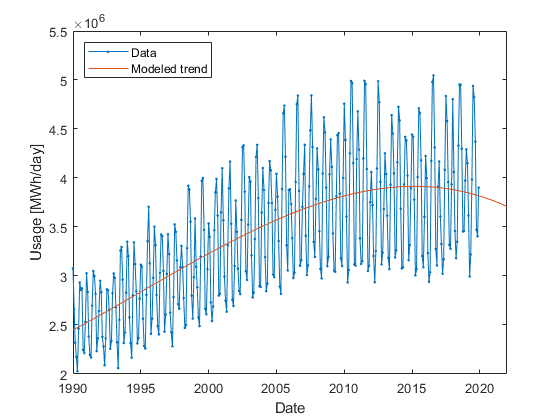

plot(dates,resUsage,".-")
hold on
datesFit = dates(1) + years(elYrFit);
plot(datesFit,resUsageFit)
% Add labels
xlabel("Date")
ylabel("Usage [MWh/day]")
legend("Data","Modeled trend","Location","northwest")
hold off

## Add annotations

Label the maximum and minimum usage with both the usage and the month in which it occurred.

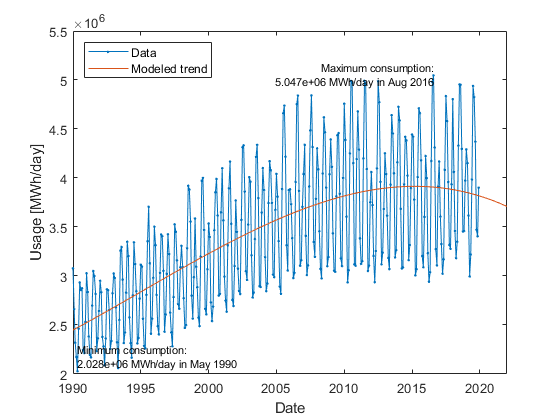

% Set the date format for display
dates.Format = "MMM yyyy";

% Minimum value
[minuse,idx] = min(resUsage);
mindate = dates(idx);
% Create string to add
mtxt = num2str(minuse,4) + " MWh/day in " + string(mindate);
% Create string array (to make a multi-line annotation)
mstring = ["Minimum consumption:", mtxt];
% Add text to graph (x value is converted to a serial date number)
text(mindate,minuse,mstring,...
    "VerticalAlignment","bottom","FontSize",8)  % some text options

% Maximum value
[maxuse,idx] = max(resUsage);
maxdate = dates(idx);
mtxt = num2str(maxuse,4) + " MWh/day in " + string(maxdate);
mstring = ["Maximum consumption:", mtxt];
text(maxdate,maxuse,mstring,...
    "HorizontalAlignment","right","FontSize",8)